Reading in data

clear
imread("data32\test\animal animal_faces cat cat_face\0BGPHALKEI6K.jpg", "jpg")

ans = 32×32×3 uint8 array
ans(:,:,1) =

   164   171   166   159   159   150   150   145   137   140   117    76    61    72    84    86    90    90    90    88    89    87    87    89    88    90    88    87    84    76    77    72
   170   172   169   158   159   155   150   143   140   141   116    75    59    71    83    86    87    88    89    88    90    92    92    88    90    93    92    86    84    82    79    71
   152   173   172   164   157   150   148   141   137   139   114    76    62    71    80    82    81    80    86    92    92    88    90    93    90    88    82    83    80    83    69    71
   150   172   165   160   156   151   146   142   136   140   116    76    62    72    79    82    80    80    85    89    90    95    95    87    85    88    81    80    76    72    72    70
   149   169   167   158   156   147   139   138   135   140   118    76    60    71    81    83    79    82    85    89    91    92    90    86    81    76    87   137   136    74    65  


imagefiles = dir("data32\test\animal animal_faces cat cat_face\*.jpg")

imagefiles = 1661×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


filepath = "data32\test\animal animal_faces cat cat_face"

filepath = "data32\test\animal animal_faces cat cat_face"

for ii=1:50
   currentfilename = imagefiles(ii).name;
   currentimage = imread(filepath + "\" +  currentfilename);
   images{ii} = currentimage;
end

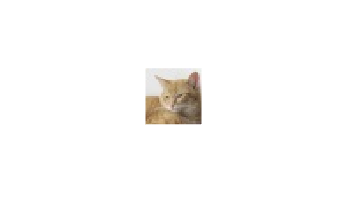

imshow(images{1})

Reproduce image

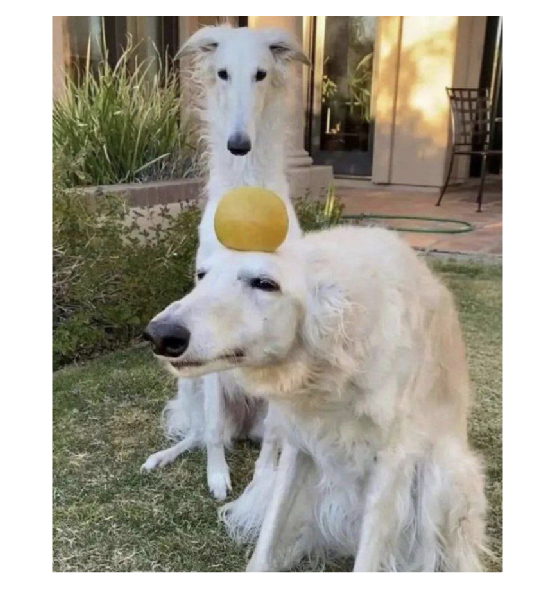

targetImage = imread("dogdogorange.png");

imshow(targetImage)


[l, h, d] = size(targetImage)

l = 867

h = 701

d = 3

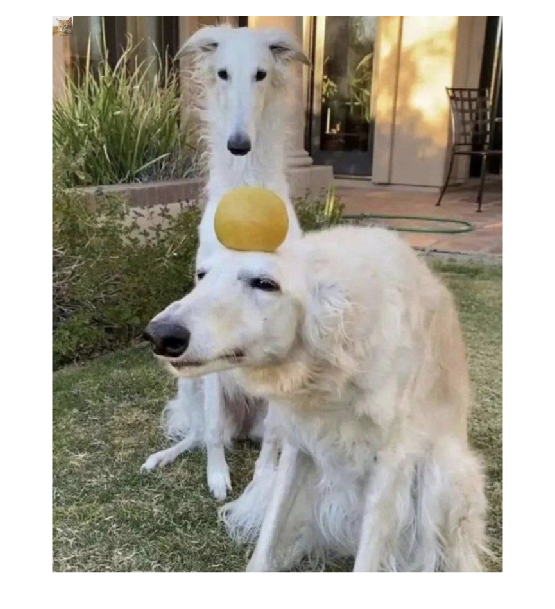


targetImage(1:32, 1:32, :) = images{1};

imshow(targetImage)

Image Segmentation

Use kmeans with random clustters to segment the image 

segmentedImage = im2double(targetImage)

segmentedImage = segmentedImage(:,:,1) =

    0.9255    0.9020    0.9098    0.9059    0.8863    0.8784    0.8980    0.8980    0.9098    0.9216    0.9176    0.9137    0.9137    0.9176    0.9137    0.8941    0.9020    0.9059    0.8902    0.8941    0.8980    0.9137    0.9137    0.9176    0.9098    0.8980    0.9294    0.9176    0.9176    0.9255    0.9294    0.9294    0.4235    0.4275    0.4157    0.4000    0.3882    0.3804    0.3804    0.3804    0.3843    0.3922    0.3922    0.3922    0.3922    0.3922    0.3922    0.3922    0.3882    0.3843    0.3843    0.3922    0.4000    0.4118    0.4157    0.4235    0.4353    0.4510    0.4627    0.5059    0.5569    0.5882    0.5882    0.5804    0.5765    0.5765    0.5804    0.5725    0.5490    0.5137    0.4824    0.4667    0.4471    0.3765    0.2824    0.2549    0.3216    0.4588    0.4863    0.3529    0.2118    0.1647    0.1608    0.1608    0.1569    0.1569    0.1569    0.1608    0.1647    0.1647    0.1686    0.1686    0.1686    0.1765    0.1804    0.16

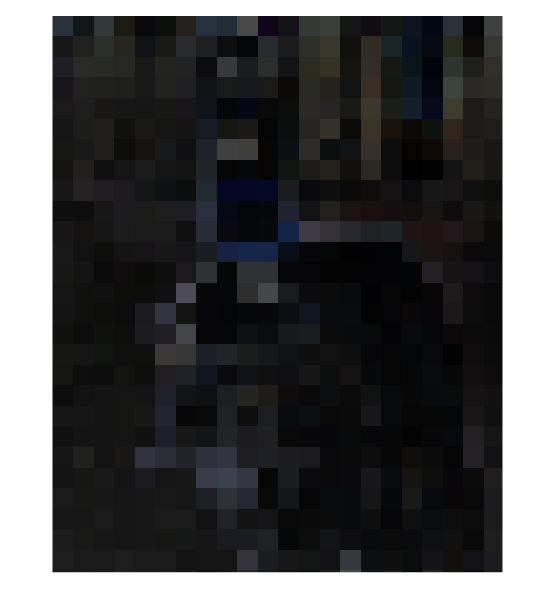

for i = 1:3
segmentedImage(:,:,i) = segmentImage(segmentedImage(:,:,i));
end

imshow(segmentedImage)

load("xyz.mat")
load("illum.mat")
load("DLP.mat")
k = 100 ./ sum(xyz(:,2)' .* CIED65)

k = 4.6460

Big Loop

rTileSize = 32;
oTileSize = 32;
[~, datasetSize] = size(images)

datasetSize = 50

[rows, cols, ~] = size(targetImage)

rows = 867

cols = 701

tileRows = ceil(rows / oTileSize)

tileRows = 28

tileCols = ceil(cols / oTileSize)

tileCols = 22


outputImage = zeros(tileRows*rTileSize, tileCols * rTileSize,3);

% go through each tile
for c = 1:tileCols
    for r = 1:tileRows
        tileRFrom = 1 + (r-1)*(oTileSize);
        tileRTo = r*oTileSize;
        if tileRTo > rows
            tileRTo = rows;
        end
        tileCFrom = 1 + (c-1)*(oTileSize);
        tileCTo = c*oTileSize;
        if tileCTo > cols
            tileCTo = cols;
        end
        currentTile = targetImage(tileRFrom:tileRTo, tileCFrom:tileCTo, :);

        % convert current Tile to xyz, might use average colour
        averageTileXYZ = averageColourXYZ(currentTile);


        bestImageIndex = 0;
        bestDeltaE = 1000;

        % find best image for each tile
        for i = 1:datasetSize
            curImg = images{i};
            % convert current sample image to xyz

            currentImageXYZ = averageColourXYZ(curImg);

            % use calcDeltaE
            [meanDeltaE, Max] = calcDeltaE(averageTileXYZ', currentImageXYZ');


            if Max < bestDeltaE
                bestDeltaE = Max;
                bestImageIndex = i;
            end

        end
        tileRTo = r*oTileSize;
        tileCTo = c*oTileSize;
        outputImage(tileRFrom:tileRTo, tileCFrom:tileCTo, :) = images{i};

    end
end

currentImageXYZ =     0.2193
    0.2572
    0.2373


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ =     0.1781
    0.2082
    0.1984


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ =     0.1229
    0.1433
    0.1513


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ =     0.1572
    0.1840
    0.1883


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ =     0.1376
    0.1620
    0.1404


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ =     0.1854
    0.2174
    0.2154


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ =     0.1229
    0.1435
    0.1407


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ =     0.1469
    0.1805
    0.1262


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ =     0.2122
    0.2439
    0.2190


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ =     0.1205
    0.1337
    0.0983


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ =     0.2000
    0.2353
    0.2249


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ =     0.1643
    0.1905
    0.1475


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ =     0.1453
    0.1681
    0.1839


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ =     0.2039
    0.2373
    0.2501


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ =     0.1288
    0.1506
    0.1443


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ =     0.1527
    0.1786
    0.1810


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ =     0.1952
    0.2282
    0.2224


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ =     0.1653
    0.1923
    0.1903


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ =     0.2524
    0.2950
    0.2993


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ =     0.1468
    0.1713
    0.1506


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ =     0.1274
    0.1484
    0.1537


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ =     0.2046
    0.2394
    0.2377


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ =     0.1404
    0.1652
    0.1534


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ =     0.1787
    0.2087
    0.2145


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ =     0.1018
    0.1187
    0.1232


averageTileXYZ =     0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.2098
    0.2473
    0.2266


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.1523
    0.1783
    0.1697


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.2088
    0.2447
    0.2444


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.0764
    0.0899
    0.0917


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.1469
    0.1714
    0.1680


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.1940
    0.2305
    0.2109


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.1798
    0.2103
    0.2208


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.1690
    0.1969
    0.1942


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.1532
    0.1801
    0.1615


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.1289
    0.1534
    0.1249


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.1605
    0.1887
    0.1812


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.1750
    0.2021
    0.1917


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.1430
    0.1679
    0.1352


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.1634
    0.1876
    0.2006


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.1455
    0.1712
    0.1508


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.1528
    0.1774
    0.1963


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.2174
    0.2579
    0.2279


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.1403
    0.1657
    0.1536


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.2112
    0.2471
    0.2367


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.1473
    0.1690
    0.1110


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.1987
    0.2302
    0.2242


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.1271
    0.1486
    0.1509


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.1686
    0.2001
    0.1805


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.1466
    0.1714
    0.1611


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.1410
    0.1641
    0.1609


averageTileXYZ = 3×1
    0.2193
    0.2572
    0.2373


currentImageXYZ = 3×1
    0.2193
    0.2572
    0.2373


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1781
    0.2082
    0.1984


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1229
    0.1433
    0.1513


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1572
    0.1840
    0.1883


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1376
    0.1620
    0.1404


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1854
    0.2174
    0.2154


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1229
    0.1435
    0.1407


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1469
    0.1805
    0.1262


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.2122
    0.2439
    0.2190


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1205
    0.1337
    0.0983


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.2000
    0.2353
    0.2249


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1643
    0.1905
    0.1475


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1453
    0.1681
    0.1839


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.2039
    0.2373
    0.2501


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1288
    0.1506
    0.1443


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1527
    0.1786
    0.1810


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1952
    0.2282
    0.2224


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1653
    0.1923
    0.1903


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.2524
    0.2950
    0.2993


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1468
    0.1713
    0.1506


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1274
    0.1484
    0.1537


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.2046
    0.2394
    0.2377


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1404
    0.1652
    0.1534


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1787
    0.2087
    0.2145


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1018
    0.1187
    0.1232


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.2098
    0.2473
    0.2266


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1523
    0.1783
    0.1697


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.2088
    0.2447
    0.2444


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.0764
    0.0899
    0.0917


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1469
    0.1714
    0.1680


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1940
    0.2305
    0.2109


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1798
    0.2103
    0.2208


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1690
    0.1969
    0.1942


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1532
    0.1801
    0.1615


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1289
    0.1534
    0.1249


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1605
    0.1887
    0.1812


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1750
    0.2021
    0.1917


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1430
    0.1679
    0.1352


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1634
    0.1876
    0.2006


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1455
    0.1712
    0.1508


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1528
    0.1774
    0.1963


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.2174
    0.2579
    0.2279


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1403
    0.1657
    0.1536


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.2112
    0.2471
    0.2367


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1473
    0.1690
    0.1110


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1987
    0.2302
    0.2242


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1271
    0.1486
    0.1509


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1686
    0.2001
    0.1805


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1466
    0.1714
    0.1611


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.1410
    0.1641
    0.1609


averageTileXYZ = 3×1
    0.1959
    0.2291
    0.2025


currentImageXYZ = 3×1
    0.2193
    0.2572
    0.2373


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1781
    0.2082
    0.1984


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1229
    0.1433
    0.1513


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1572
    0.1840
    0.1883


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1376
    0.1620
    0.1404


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1854
    0.2174
    0.2154


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1229
    0.1435
    0.1407


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1469
    0.1805
    0.1262


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.2122
    0.2439
    0.2190


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1205
    0.1337
    0.0983


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.2000
    0.2353
    0.2249


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1643
    0.1905
    0.1475


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1453
    0.1681
    0.1839


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.2039
    0.2373
    0.2501


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1288
    0.1506
    0.1443


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1527
    0.1786
    0.1810


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1952
    0.2282
    0.2224


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1653
    0.1923
    0.1903


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.2524
    0.2950
    0.2993


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1468
    0.1713
    0.1506


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1274
    0.1484
    0.1537


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.2046
    0.2394
    0.2377


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1404
    0.1652
    0.1534


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1787
    0.2087
    0.2145


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1018
    0.1187
    0.1232


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.2098
    0.2473
    0.2266


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1523
    0.1783
    0.1697


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.2088
    0.2447
    0.2444


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.0764
    0.0899
    0.0917


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1469
    0.1714
    0.1680


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1940
    0.2305
    0.2109


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1798
    0.2103
    0.2208


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1690
    0.1969
    0.1942


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1532
    0.1801
    0.1615


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1289
    0.1534
    0.1249


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1605
    0.1887
    0.1812


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1750
    0.2021
    0.1917


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1430
    0.1679
    0.1352


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1634
    0.1876
    0.2006


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1455
    0.1712
    0.1508


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1528
    0.1774
    0.1963


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.2174
    0.2579
    0.2279


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1403
    0.1657
    0.1536


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.2112
    0.2471
    0.2367


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1473
    0.1690
    0.1110


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1987
    0.2302
    0.2242


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1271
    0.1486
    0.1509


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1686
    0.2001
    0.1805


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1466
    0.1714
    0.1611


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.1410
    0.1641
    0.1609


averageTileXYZ = 3×1
    0.1962
    0.2301
    0.2006


currentImageXYZ = 3×1
    0.2193
    0.2572
    0.2373


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1781
    0.2082
    0.1984


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1229
    0.1433
    0.1513


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1572
    0.1840
    0.1883


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1376
    0.1620
    0.1404


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1854
    0.2174
    0.2154


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1229
    0.1435
    0.1407


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1469
    0.1805
    0.1262


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.2122
    0.2439
    0.2190


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1205
    0.1337
    0.0983


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.2000
    0.2353
    0.2249


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1643
    0.1905
    0.1475


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1453
    0.1681
    0.1839


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.2039
    0.2373
    0.2501


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1288
    0.1506
    0.1443


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1527
    0.1786
    0.1810


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1952
    0.2282
    0.2224


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1653
    0.1923
    0.1903


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.2524
    0.2950
    0.2993


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1468
    0.1713
    0.1506


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1274
    0.1484
    0.1537


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.2046
    0.2394
    0.2377


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1404
    0.1652
    0.1534


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1787
    0.2087
    0.2145


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1018
    0.1187
    0.1232


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.2098
    0.2473
    0.2266


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1523
    0.1783
    0.1697


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.2088
    0.2447
    0.2444


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.0764
    0.0899
    0.0917


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1469
    0.1714
    0.1680


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1940
    0.2305
    0.2109


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1798
    0.2103
    0.2208


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1690
    0.1969
    0.1942


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1532
    0.1801
    0.1615


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1289
    0.1534
    0.1249


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1605
    0.1887
    0.1812


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1750
    0.2021
    0.1917


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1430
    0.1679
    0.1352


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1634
    0.1876
    0.2006


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1455
    0.1712
    0.1508


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1528
    0.1774
    0.1963


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.2174
    0.2579
    0.2279


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1403
    0.1657
    0.1536


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.2112
    0.2471
    0.2367


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1473
    0.1690
    0.1110


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1987
    0.2302
    0.2242


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1271
    0.1486
    0.1509


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1686
    0.2001
    0.1805


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1466
    0.1714
    0.1611


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.1410
    0.1641
    0.1609


averageTileXYZ = 3×1
    0.2150
    0.2542
    0.2222


currentImageXYZ = 3×1
    0.2193
    0.2572
    0.2373


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1781
    0.2082
    0.1984


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1229
    0.1433
    0.1513


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1572
    0.1840
    0.1883


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1376
    0.1620
    0.1404


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1854
    0.2174
    0.2154


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1229
    0.1435
    0.1407


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1469
    0.1805
    0.1262


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.2122
    0.2439
    0.2190


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1205
    0.1337
    0.0983


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.2000
    0.2353
    0.2249


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1643
    0.1905
    0.1475


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1453
    0.1681
    0.1839


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.2039
    0.2373
    0.2501


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1288
    0.1506
    0.1443


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1527
    0.1786
    0.1810


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1952
    0.2282
    0.2224


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1653
    0.1923
    0.1903


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.2524
    0.2950
    0.2993


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1468
    0.1713
    0.1506


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1274
    0.1484
    0.1537


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.2046
    0.2394
    0.2377


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1404
    0.1652
    0.1534


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1787
    0.2087
    0.2145


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1018
    0.1187
    0.1232


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.2098
    0.2473
    0.2266


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1523
    0.1783
    0.1697


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.2088
    0.2447
    0.2444


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.0764
    0.0899
    0.0917


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1469
    0.1714
    0.1680


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1940
    0.2305
    0.2109


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1798
    0.2103
    0.2208


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1690
    0.1969
    0.1942


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1532
    0.1801
    0.1615


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1289
    0.1534
    0.1249


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1605
    0.1887
    0.1812


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1750
    0.2021
    0.1917


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1430
    0.1679
    0.1352


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1634
    0.1876
    0.2006


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1455
    0.1712
    0.1508


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1528
    0.1774
    0.1963


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.2174
    0.2579
    0.2279


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1403
    0.1657
    0.1536


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.2112
    0.2471
    0.2367


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1473
    0.1690
    0.1110


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1987
    0.2302
    0.2242


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1271
    0.1486
    0.1509


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1686
    0.2001
    0.1805


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1466
    0.1714
    0.1611


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.1410
    0.1641
    0.1609


averageTileXYZ = 3×1
    0.1899
    0.2293
    0.1823


currentImageXYZ = 3×1
    0.2193
    0.2572
    0.2373


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1781
    0.2082
    0.1984


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1229
    0.1433
    0.1513


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1572
    0.1840
    0.1883


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1376
    0.1620
    0.1404


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1854
    0.2174
    0.2154


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1229
    0.1435
    0.1407


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1469
    0.1805
    0.1262


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.2122
    0.2439
    0.2190


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1205
    0.1337
    0.0983


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.2000
    0.2353
    0.2249


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1643
    0.1905
    0.1475


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1453
    0.1681
    0.1839


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.2039
    0.2373
    0.2501


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1288
    0.1506
    0.1443


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1527
    0.1786
    0.1810


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1952
    0.2282
    0.2224


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1653
    0.1923
    0.1903


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.2524
    0.2950
    0.2993


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1468
    0.1713
    0.1506


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1274
    0.1484
    0.1537


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.2046
    0.2394
    0.2377


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1404
    0.1652
    0.1534


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1787
    0.2087
    0.2145


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1018
    0.1187
    0.1232


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.2098
    0.2473
    0.2266


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1523
    0.1783
    0.1697


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.2088
    0.2447
    0.2444


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.0764
    0.0899
    0.0917


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1469
    0.1714
    0.1680


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1940
    0.2305
    0.2109


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1798
    0.2103
    0.2208


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1690
    0.1969
    0.1942


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1532
    0.1801
    0.1615


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1289
    0.1534
    0.1249


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1605
    0.1887
    0.1812


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1750
    0.2021
    0.1917


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1430
    0.1679
    0.1352


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1634
    0.1876
    0.2006


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1455
    0.1712
    0.1508


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1528
    0.1774
    0.1963


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.2174
    0.2579
    0.2279


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1403
    0.1657
    0.1536


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.2112
    0.2471
    0.2367


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1473
    0.1690
    0.1110


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1987
    0.2302
    0.2242


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1271
    0.1486
    0.1509


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1686
    0.2001
    0.1805


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1466
    0.1714
    0.1611


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.1410
    0.1641
    0.1609


averageTileXYZ = 3×1
    0.1339
    0.1659
    0.1166


currentImageXYZ = 3×1
    0.2193
    0.2572
    0.2373


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1781
    0.2082
    0.1984


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1229
    0.1433
    0.1513


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1572
    0.1840
    0.1883


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1376
    0.1620
    0.1404


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1854
    0.2174
    0.2154


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1229
    0.1435
    0.1407


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1469
    0.1805
    0.1262


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.2122
    0.2439
    0.2190


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1205
    0.1337
    0.0983


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.2000
    0.2353
    0.2249


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1643
    0.1905
    0.1475


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1453
    0.1681
    0.1839


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.2039
    0.2373
    0.2501


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1288
    0.1506
    0.1443


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1527
    0.1786
    0.1810


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1952
    0.2282
    0.2224


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1653
    0.1923
    0.1903


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.2524
    0.2950
    0.2993


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1468
    0.1713
    0.1506


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1274
    0.1484
    0.1537


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.2046
    0.2394
    0.2377


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1404
    0.1652
    0.1534


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1787
    0.2087
    0.2145


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1018
    0.1187
    0.1232


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.2098
    0.2473
    0.2266


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1523
    0.1783
    0.1697


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.2088
    0.2447
    0.2444


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.0764
    0.0899
    0.0917


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1469
    0.1714
    0.1680


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1940
    0.2305
    0.2109


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1798
    0.2103
    0.2208


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1690
    0.1969
    0.1942


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1532
    0.1801
    0.1615


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1289
    0.1534
    0.1249


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1605
    0.1887
    0.1812


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1750
    0.2021
    0.1917


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1430
    0.1679
    0.1352


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1634
    0.1876
    0.2006


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1455
    0.1712
    0.1508


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1528
    0.1774
    0.1963


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.2174
    0.2579
    0.2279


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1403
    0.1657
    0.1536


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.2112
    0.2471
    0.2367


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1473
    0.1690
    0.1110


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1987
    0.2302
    0.2242


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1271
    0.1486
    0.1509


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1686
    0.2001
    0.1805


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1466
    0.1714
    0.1611


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.1410
    0.1641
    0.1609


averageTileXYZ = 3×1
    0.1390
    0.1705
    0.1276


currentImageXYZ = 3×1
    0.2193
    0.2572
    0.2373


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1781
    0.2082
    0.1984


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1229
    0.1433
    0.1513


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1572
    0.1840
    0.1883


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1376
    0.1620
    0.1404


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1854
    0.2174
    0.2154


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1229
    0.1435
    0.1407


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1469
    0.1805
    0.1262


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.2122
    0.2439
    0.2190


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1205
    0.1337
    0.0983


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.2000
    0.2353
    0.2249


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1643
    0.1905
    0.1475


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1453
    0.1681
    0.1839


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.2039
    0.2373
    0.2501


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1288
    0.1506
    0.1443


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1527
    0.1786
    0.1810


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1952
    0.2282
    0.2224


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1653
    0.1923
    0.1903


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.2524
    0.2950
    0.2993


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1468
    0.1713
    0.1506


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1274
    0.1484
    0.1537


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.2046
    0.2394
    0.2377


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1404
    0.1652
    0.1534


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1787
    0.2087
    0.2145


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1018
    0.1187
    0.1232


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.2098
    0.2473
    0.2266


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1523
    0.1783
    0.1697


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.2088
    0.2447
    0.2444


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.0764
    0.0899
    0.0917


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1469
    0.1714
    0.1680


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1940
    0.2305
    0.2109


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1798
    0.2103
    0.2208


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1690
    0.1969
    0.1942


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1532
    0.1801
    0.1615


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1289
    0.1534
    0.1249


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1605
    0.1887
    0.1812


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1750
    0.2021
    0.1917


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1430
    0.1679
    0.1352


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1634
    0.1876
    0.2006


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1455
    0.1712
    0.1508


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1528
    0.1774
    0.1963


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.2174
    0.2579
    0.2279


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1403
    0.1657
    0.1536


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.2112
    0.2471
    0.2367


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1473
    0.1690
    0.1110


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1987
    0.2302
    0.2242


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1271
    0.1486
    0.1509


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1686
    0.2001
    0.1805


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1466
    0.1714
    0.1611


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.1410
    0.1641
    0.1609


averageTileXYZ = 3×1
    0.1307
    0.1593
    0.1211


currentImageXYZ = 3×1
    0.2193
    0.2572
    0.2373


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1781
    0.2082
    0.1984


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1229
    0.1433
    0.1513


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1572
    0.1840
    0.1883


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1376
    0.1620
    0.1404


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1854
    0.2174
    0.2154


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1229
    0.1435
    0.1407


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1469
    0.1805
    0.1262


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.2122
    0.2439
    0.2190


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1205
    0.1337
    0.0983


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.2000
    0.2353
    0.2249


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1643
    0.1905
    0.1475


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1453
    0.1681
    0.1839


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.2039
    0.2373
    0.2501


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1288
    0.1506
    0.1443


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1527
    0.1786
    0.1810


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1952
    0.2282
    0.2224


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1653
    0.1923
    0.1903


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.2524
    0.2950
    0.2993


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1468
    0.1713
    0.1506


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1274
    0.1484
    0.1537


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.2046
    0.2394
    0.2377


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1404
    0.1652
    0.1534


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1787
    0.2087
    0.2145


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1018
    0.1187
    0.1232


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.2098
    0.2473
    0.2266


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1523
    0.1783
    0.1697


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.2088
    0.2447
    0.2444


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.0764
    0.0899
    0.0917


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1469
    0.1714
    0.1680


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1940
    0.2305
    0.2109


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1798
    0.2103
    0.2208


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1690
    0.1969
    0.1942


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1532
    0.1801
    0.1615


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1289
    0.1534
    0.1249


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1605
    0.1887
    0.1812


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1750
    0.2021
    0.1917


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1430
    0.1679
    0.1352


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1634
    0.1876
    0.2006


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1455
    0.1712
    0.1508


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1528
    0.1774
    0.1963


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.2174
    0.2579
    0.2279


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1403
    0.1657
    0.1536


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.2112
    0.2471
    0.2367


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1473
    0.1690
    0.1110


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1987
    0.2302
    0.2242


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1271
    0.1486
    0.1509


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1686
    0.2001
    0.1805


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1466
    0.1714
    0.1611


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.1410
    0.1641
    0.1609


averageTileXYZ = 3×1
    0.1356
    0.1646
    0.1292


currentImageXYZ = 3×1
    0.2193
    0.2572
    0.2373


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1781
    0.2082
    0.1984


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1229
    0.1433
    0.1513


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1572
    0.1840
    0.1883


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1376
    0.1620
    0.1404


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1854
    0.2174
    0.2154


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1229
    0.1435
    0.1407


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1469
    0.1805
    0.1262


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.2122
    0.2439
    0.2190


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1205
    0.1337
    0.0983


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.2000
    0.2353
    0.2249


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1643
    0.1905
    0.1475


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1453
    0.1681
    0.1839


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.2039
    0.2373
    0.2501


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1288
    0.1506
    0.1443


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1527
    0.1786
    0.1810


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1952
    0.2282
    0.2224


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1653
    0.1923
    0.1903


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.2524
    0.2950
    0.2993


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1468
    0.1713
    0.1506


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1274
    0.1484
    0.1537


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.2046
    0.2394
    0.2377


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1404
    0.1652
    0.1534


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1787
    0.2087
    0.2145


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1018
    0.1187
    0.1232


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.2098
    0.2473
    0.2266


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1523
    0.1783
    0.1697


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.2088
    0.2447
    0.2444


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.0764
    0.0899
    0.0917


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1469
    0.1714
    0.1680


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1940
    0.2305
    0.2109


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1798
    0.2103
    0.2208


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1690
    0.1969
    0.1942


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1532
    0.1801
    0.1615


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1289
    0.1534
    0.1249


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1605
    0.1887
    0.1812


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1750
    0.2021
    0.1917


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1430
    0.1679
    0.1352


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1634
    0.1876
    0.2006


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1455
    0.1712
    0.1508


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1528
    0.1774
    0.1963


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.2174
    0.2579
    0.2279


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1403
    0.1657
    0.1536


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.2112
    0.2471
    0.2367


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1473
    0.1690
    0.1110


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1987
    0.2302
    0.2242


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1271
    0.1486
    0.1509


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1686
    0.2001
    0.1805


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1466
    0.1714
    0.1611


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.1410
    0.1641
    0.1609


averageTileXYZ = 3×1
    0.1142
    0.1407
    0.0957


currentImageXYZ = 3×1
    0.2193
    0.2572
    0.2373


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1781
    0.2082
    0.1984


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1229
    0.1433
    0.1513


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1572
    0.1840
    0.1883


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1376
    0.1620
    0.1404


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1854
    0.2174
    0.2154


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1229
    0.1435
    0.1407


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1469
    0.1805
    0.1262


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.2122
    0.2439
    0.2190


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1205
    0.1337
    0.0983


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.2000
    0.2353
    0.2249


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1643
    0.1905
    0.1475


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1453
    0.1681
    0.1839


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.2039
    0.2373
    0.2501


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1288
    0.1506
    0.1443


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1527
    0.1786
    0.1810


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1952
    0.2282
    0.2224


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1653
    0.1923
    0.1903


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.2524
    0.2950
    0.2993


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1468
    0.1713
    0.1506


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1274
    0.1484
    0.1537


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.2046
    0.2394
    0.2377


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1404
    0.1652
    0.1534


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1787
    0.2087
    0.2145


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1018
    0.1187
    0.1232


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.2098
    0.2473
    0.2266


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1523
    0.1783
    0.1697


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.2088
    0.2447
    0.2444


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.0764
    0.0899
    0.0917


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1469
    0.1714
    0.1680


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1940
    0.2305
    0.2109


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1798
    0.2103
    0.2208


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1690
    0.1969
    0.1942


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1532
    0.1801
    0.1615


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1289
    0.1534
    0.1249


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1605
    0.1887
    0.1812


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1750
    0.2021
    0.1917


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1430
    0.1679
    0.1352


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1634
    0.1876
    0.2006


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1455
    0.1712
    0.1508


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1528
    0.1774
    0.1963


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.2174
    0.2579
    0.2279


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1403
    0.1657
    0.1536


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.2112
    0.2471
    0.2367


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1473
    0.1690
    0.1110


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1987
    0.2302
    0.2242


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1271
    0.1486
    0.1509


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1686
    0.2001
    0.1805


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1466
    0.1714
    0.1611


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.1410
    0.1641
    0.1609


averageTileXYZ = 3×1
    0.1065
    0.1298
    0.0956


currentImageXYZ = 3×1
    0.2193
    0.2572
    0.2373


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1781
    0.2082
    0.1984


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1229
    0.1433
    0.1513


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1572
    0.1840
    0.1883


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1376
    0.1620
    0.1404


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1854
    0.2174
    0.2154


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1229
    0.1435
    0.1407


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1469
    0.1805
    0.1262


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.2122
    0.2439
    0.2190


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1205
    0.1337
    0.0983


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.2000
    0.2353
    0.2249


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1643
    0.1905
    0.1475


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1453
    0.1681
    0.1839


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.2039
    0.2373
    0.2501


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1288
    0.1506
    0.1443


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1527
    0.1786
    0.1810


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1952
    0.2282
    0.2224


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1653
    0.1923
    0.1903


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.2524
    0.2950
    0.2993


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1468
    0.1713
    0.1506


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1274
    0.1484
    0.1537


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.2046
    0.2394
    0.2377


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1404
    0.1652
    0.1534


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1787
    0.2087
    0.2145


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1018
    0.1187
    0.1232


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.2098
    0.2473
    0.2266


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1523
    0.1783
    0.1697


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.2088
    0.2447
    0.2444


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.0764
    0.0899
    0.0917


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1469
    0.1714
    0.1680


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1940
    0.2305
    0.2109


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1798
    0.2103
    0.2208


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1690
    0.1969
    0.1942


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1532
    0.1801
    0.1615


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1289
    0.1534
    0.1249


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1605
    0.1887
    0.1812


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1750
    0.2021
    0.1917


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1430
    0.1679
    0.1352


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1634
    0.1876
    0.2006


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1455
    0.1712
    0.1508


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1528
    0.1774
    0.1963


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.2174
    0.2579
    0.2279


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1403
    0.1657
    0.1536


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.2112
    0.2471
    0.2367


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1473
    0.1690
    0.1110


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1987
    0.2302
    0.2242


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1271
    0.1486
    0.1509


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1686
    0.2001
    0.1805


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1466
    0.1714
    0.1611


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.1410
    0.1641
    0.1609


averageTileXYZ = 3×1
    0.1102
    0.1325
    0.1090


currentImageXYZ = 3×1
    0.2193
    0.2572
    0.2373


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1781
    0.2082
    0.1984


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1229
    0.1433
    0.1513


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1572
    0.1840
    0.1883


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1376
    0.1620
    0.1404


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1854
    0.2174
    0.2154


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1229
    0.1435
    0.1407


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1469
    0.1805
    0.1262


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.2122
    0.2439
    0.2190


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1205
    0.1337
    0.0983


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.2000
    0.2353
    0.2249


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1643
    0.1905
    0.1475


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1453
    0.1681
    0.1839


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.2039
    0.2373
    0.2501


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1288
    0.1506
    0.1443


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1527
    0.1786
    0.1810


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1952
    0.2282
    0.2224


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1653
    0.1923
    0.1903


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.2524
    0.2950
    0.2993


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1468
    0.1713
    0.1506


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1274
    0.1484
    0.1537


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.2046
    0.2394
    0.2377


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1404
    0.1652
    0.1534


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1787
    0.2087
    0.2145


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1018
    0.1187
    0.1232


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.2098
    0.2473
    0.2266


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1523
    0.1783
    0.1697


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.2088
    0.2447
    0.2444


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.0764
    0.0899
    0.0917


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1469
    0.1714
    0.1680


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1940
    0.2305
    0.2109


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1798
    0.2103
    0.2208


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1690
    0.1969
    0.1942


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1532
    0.1801
    0.1615


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1289
    0.1534
    0.1249


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1605
    0.1887
    0.1812


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1750
    0.2021
    0.1917


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1430
    0.1679
    0.1352


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1634
    0.1876
    0.2006


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1455
    0.1712
    0.1508


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1528
    0.1774
    0.1963


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.2174
    0.2579
    0.2279


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1403
    0.1657
    0.1536


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.2112
    0.2471
    0.2367


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1473
    0.1690
    0.1110


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1987
    0.2302
    0.2242


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1271
    0.1486
    0.1509


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1686
    0.2001
    0.1805


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1466
    0.1714
    0.1611


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.1410
    0.1641
    0.1609


averageTileXYZ = 3×1
    0.1104
    0.1313
    0.1159


currentImageXYZ = 3×1
    0.2193
    0.2572
    0.2373


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1781
    0.2082
    0.1984


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1229
    0.1433
    0.1513


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1572
    0.1840
    0.1883


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1376
    0.1620
    0.1404


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1854
    0.2174
    0.2154


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1229
    0.1435
    0.1407


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1469
    0.1805
    0.1262


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.2122
    0.2439
    0.2190


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1205
    0.1337
    0.0983


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.2000
    0.2353
    0.2249


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1643
    0.1905
    0.1475


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1453
    0.1681
    0.1839


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.2039
    0.2373
    0.2501


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1288
    0.1506
    0.1443


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1527
    0.1786
    0.1810


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1952
    0.2282
    0.2224


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1653
    0.1923
    0.1903


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.2524
    0.2950
    0.2993


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1468
    0.1713
    0.1506


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1274
    0.1484
    0.1537


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.2046
    0.2394
    0.2377


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1404
    0.1652
    0.1534


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1787
    0.2087
    0.2145


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1018
    0.1187
    0.1232


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.2098
    0.2473
    0.2266


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1523
    0.1783
    0.1697


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.2088
    0.2447
    0.2444


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.0764
    0.0899
    0.0917


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1469
    0.1714
    0.1680


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1940
    0.2305
    0.2109


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1798
    0.2103
    0.2208


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1690
    0.1969
    0.1942


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1532
    0.1801
    0.1615


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1289
    0.1534
    0.1249


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1605
    0.1887
    0.1812


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1750
    0.2021
    0.1917


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1430
    0.1679
    0.1352


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1634
    0.1876
    0.2006


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1455
    0.1712
    0.1508


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1528
    0.1774
    0.1963


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.2174
    0.2579
    0.2279


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1403
    0.1657
    0.1536


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.2112
    0.2471
    0.2367


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1473
    0.1690
    0.1110


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1987
    0.2302
    0.2242


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1271
    0.1486
    0.1509


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1686
    0.2001
    0.1805


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1466
    0.1714
    0.1611


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.1410
    0.1641
    0.1609


averageTileXYZ = 3×1
    0.0915
    0.1083
    0.0963


currentImageXYZ = 3×1
    0.2193
    0.2572
    0.2373


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1781
    0.2082
    0.1984


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1229
    0.1433
    0.1513


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1572
    0.1840
    0.1883


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1376
    0.1620
    0.1404


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1854
    0.2174
    0.2154


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1229
    0.1435
    0.1407


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1469
    0.1805
    0.1262


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.2122
    0.2439
    0.2190


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1205
    0.1337
    0.0983


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.2000
    0.2353
    0.2249


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1643
    0.1905
    0.1475


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1453
    0.1681
    0.1839


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.2039
    0.2373
    0.2501


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1288
    0.1506
    0.1443


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1527
    0.1786
    0.1810


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1952
    0.2282
    0.2224


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1653
    0.1923
    0.1903


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.2524
    0.2950
    0.2993


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1468
    0.1713
    0.1506


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1274
    0.1484
    0.1537


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.2046
    0.2394
    0.2377


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1404
    0.1652
    0.1534


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1787
    0.2087
    0.2145


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1018
    0.1187
    0.1232


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.2098
    0.2473
    0.2266


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1523
    0.1783
    0.1697


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.2088
    0.2447
    0.2444


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.0764
    0.0899
    0.0917


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1469
    0.1714
    0.1680


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1940
    0.2305
    0.2109


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1798
    0.2103
    0.2208


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1690
    0.1969
    0.1942


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1532
    0.1801
    0.1615


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1289
    0.1534
    0.1249


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1605
    0.1887
    0.1812


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1750
    0.2021
    0.1917


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1430
    0.1679
    0.1352


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1634
    0.1876
    0.2006


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1455
    0.1712
    0.1508


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1528
    0.1774
    0.1963


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.2174
    0.2579
    0.2279


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1403
    0.1657
    0.1536


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.2112
    0.2471
    0.2367


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1473
    0.1690
    0.1110


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1987
    0.2302
    0.2242


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1271
    0.1486
    0.1509


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1686
    0.2001
    0.1805


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1466
    0.1714
    0.1611


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.1410
    0.1641
    0.1609


averageTileXYZ = 3×1
    0.0807
    0.0963
    0.0874


currentImageXYZ = 3×1
    0.2193
    0.2572
    0.2373


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1781
    0.2082
    0.1984


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1229
    0.1433
    0.1513


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1572
    0.1840
    0.1883


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1376
    0.1620
    0.1404


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1854
    0.2174
    0.2154


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1229
    0.1435
    0.1407


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1469
    0.1805
    0.1262


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.2122
    0.2439
    0.2190


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1205
    0.1337
    0.0983


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.2000
    0.2353
    0.2249


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1643
    0.1905
    0.1475


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1453
    0.1681
    0.1839


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.2039
    0.2373
    0.2501


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1288
    0.1506
    0.1443


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1527
    0.1786
    0.1810


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1952
    0.2282
    0.2224


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1653
    0.1923
    0.1903


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.2524
    0.2950
    0.2993


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1468
    0.1713
    0.1506


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1274
    0.1484
    0.1537


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.2046
    0.2394
    0.2377


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1404
    0.1652
    0.1534


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1787
    0.2087
    0.2145


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1018
    0.1187
    0.1232


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.2098
    0.2473
    0.2266


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1523
    0.1783
    0.1697


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.2088
    0.2447
    0.2444


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.0764
    0.0899
    0.0917


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1469
    0.1714
    0.1680


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1940
    0.2305
    0.2109


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1798
    0.2103
    0.2208


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1690
    0.1969
    0.1942


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1532
    0.1801
    0.1615


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1289
    0.1534
    0.1249


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1605
    0.1887
    0.1812


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1750
    0.2021
    0.1917


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1430
    0.1679
    0.1352


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1634
    0.1876
    0.2006


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1455
    0.1712
    0.1508


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1528
    0.1774
    0.1963


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.2174
    0.2579
    0.2279


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1403
    0.1657
    0.1536


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.2112
    0.2471
    0.2367


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1473
    0.1690
    0.1110


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1987
    0.2302
    0.2242


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1271
    0.1486
    0.1509


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1686
    0.2001
    0.1805


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1466
    0.1714
    0.1611


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.1410
    0.1641
    0.1609


averageTileXYZ = 3×1
    0.0877
    0.1086
    0.0799


currentImageXYZ = 3×1
    0.2193
    0.2572
    0.2373


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1781
    0.2082
    0.1984


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1229
    0.1433
    0.1513


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1572
    0.1840
    0.1883


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1376
    0.1620
    0.1404


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1854
    0.2174
    0.2154


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1229
    0.1435
    0.1407


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1469
    0.1805
    0.1262


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.2122
    0.2439
    0.2190


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1205
    0.1337
    0.0983


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.2000
    0.2353
    0.2249


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1643
    0.1905
    0.1475


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1453
    0.1681
    0.1839


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.2039
    0.2373
    0.2501


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1288
    0.1506
    0.1443


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1527
    0.1786
    0.1810


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1952
    0.2282
    0.2224


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1653
    0.1923
    0.1903


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.2524
    0.2950
    0.2993


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1468
    0.1713
    0.1506


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1274
    0.1484
    0.1537


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.2046
    0.2394
    0.2377


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1404
    0.1652
    0.1534


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1787
    0.2087
    0.2145


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1018
    0.1187
    0.1232


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.2098
    0.2473
    0.2266


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1523
    0.1783
    0.1697


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.2088
    0.2447
    0.2444


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.0764
    0.0899
    0.0917


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1469
    0.1714
    0.1680


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1940
    0.2305
    0.2109


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1798
    0.2103
    0.2208


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1690
    0.1969
    0.1942


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1532
    0.1801
    0.1615


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1289
    0.1534
    0.1249


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1605
    0.1887
    0.1812


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1750
    0.2021
    0.1917


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1430
    0.1679
    0.1352


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1634
    0.1876
    0.2006


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1455
    0.1712
    0.1508


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1528
    0.1774
    0.1963


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.2174
    0.2579
    0.2279


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1403
    0.1657
    0.1536


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.2112
    0.2471
    0.2367


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1473
    0.1690
    0.1110


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1987
    0.2302
    0.2242


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1271
    0.1486
    0.1509


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1686
    0.2001
    0.1805


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1466
    0.1714
    0.1611


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.1410
    0.1641
    0.1609


averageTileXYZ = 3×1
    0.0698
    0.0864
    0.0624


currentImageXYZ = 3×1
    0.2193
    0.2572
    0.2373


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1781
    0.2082
    0.1984


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1229
    0.1433
    0.1513


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1572
    0.1840
    0.1883


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1376
    0.1620
    0.1404


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1854
    0.2174
    0.2154


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1229
    0.1435
    0.1407


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1469
    0.1805
    0.1262


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.2122
    0.2439
    0.2190


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1205
    0.1337
    0.0983


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.2000
    0.2353
    0.2249


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1643
    0.1905
    0.1475


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1453
    0.1681
    0.1839


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.2039
    0.2373
    0.2501


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1288
    0.1506
    0.1443


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1527
    0.1786
    0.1810


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1952
    0.2282
    0.2224


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1653
    0.1923
    0.1903


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.2524
    0.2950
    0.2993


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1468
    0.1713
    0.1506


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1274
    0.1484
    0.1537


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.2046
    0.2394
    0.2377


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1404
    0.1652
    0.1534


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1787
    0.2087
    0.2145


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1018
    0.1187
    0.1232


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.2098
    0.2473
    0.2266


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1523
    0.1783
    0.1697


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.2088
    0.2447
    0.2444


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.0764
    0.0899
    0.0917


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1469
    0.1714
    0.1680


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1940
    0.2305
    0.2109


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1798
    0.2103
    0.2208


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1690
    0.1969
    0.1942


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1532
    0.1801
    0.1615


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1289
    0.1534
    0.1249


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1605
    0.1887
    0.1812


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1750
    0.2021
    0.1917


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1430
    0.1679
    0.1352


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1634
    0.1876
    0.2006


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1455
    0.1712
    0.1508


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1528
    0.1774
    0.1963


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.2174
    0.2579
    0.2279


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1403
    0.1657
    0.1536


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.2112
    0.2471
    0.2367


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1473
    0.1690
    0.1110


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1987
    0.2302
    0.2242


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1271
    0.1486
    0.1509


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1686
    0.2001
    0.1805


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1466
    0.1714
    0.1611


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.1410
    0.1641
    0.1609


averageTileXYZ = 3×1
    0.1173
    0.1428
    0.1166


currentImageXYZ = 3×1
    0.2193
    0.2572
    0.2373


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1781
    0.2082
    0.1984


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1229
    0.1433
    0.1513


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1572
    0.1840
    0.1883


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1376
    0.1620
    0.1404


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1854
    0.2174
    0.2154


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1229
    0.1435
    0.1407


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1469
    0.1805
    0.1262


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.2122
    0.2439
    0.2190


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1205
    0.1337
    0.0983


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.2000
    0.2353
    0.2249


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1643
    0.1905
    0.1475


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1453
    0.1681
    0.1839


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.2039
    0.2373
    0.2501


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1288
    0.1506
    0.1443


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1527
    0.1786
    0.1810


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1952
    0.2282
    0.2224


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1653
    0.1923
    0.1903


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.2524
    0.2950
    0.2993


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1468
    0.1713
    0.1506


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1274
    0.1484
    0.1537


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.2046
    0.2394
    0.2377


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1404
    0.1652
    0.1534


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1787
    0.2087
    0.2145


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1018
    0.1187
    0.1232


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.2098
    0.2473
    0.2266


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1523
    0.1783
    0.1697


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.2088
    0.2447
    0.2444


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.0764
    0.0899
    0.0917


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1469
    0.1714
    0.1680


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1940
    0.2305
    0.2109


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1798
    0.2103
    0.2208


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1690
    0.1969
    0.1942


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1532
    0.1801
    0.1615


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1289
    0.1534
    0.1249


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1605
    0.1887
    0.1812


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1750
    0.2021
    0.1917


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1430
    0.1679
    0.1352


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1634
    0.1876
    0.2006


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1455
    0.1712
    0.1508


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1528
    0.1774
    0.1963


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.2174
    0.2579
    0.2279


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1403
    0.1657
    0.1536


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.2112
    0.2471
    0.2367


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1473
    0.1690
    0.1110


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1987
    0.2302
    0.2242


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1271
    0.1486
    0.1509


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1686
    0.2001
    0.1805


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1466
    0.1714
    0.1611


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.1410
    0.1641
    0.1609


averageTileXYZ = 3×1
    0.1159
    0.1425
    0.1113


currentImageXYZ = 3×1
    0.2193
    0.2572
    0.2373


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1781
    0.2082
    0.1984


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1229
    0.1433
    0.1513


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1572
    0.1840
    0.1883


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1376
    0.1620
    0.1404


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1854
    0.2174
    0.2154


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1229
    0.1435
    0.1407


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1469
    0.1805
    0.1262


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.2122
    0.2439
    0.2190


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1205
    0.1337
    0.0983


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.2000
    0.2353
    0.2249


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1643
    0.1905
    0.1475


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1453
    0.1681
    0.1839


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.2039
    0.2373
    0.2501


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1288
    0.1506
    0.1443


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1527
    0.1786
    0.1810


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1952
    0.2282
    0.2224


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1653
    0.1923
    0.1903


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.2524
    0.2950
    0.2993


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1468
    0.1713
    0.1506


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1274
    0.1484
    0.1537


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.2046
    0.2394
    0.2377


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1404
    0.1652
    0.1534


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1787
    0.2087
    0.2145


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1018
    0.1187
    0.1232


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.2098
    0.2473
    0.2266


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1523
    0.1783
    0.1697


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.2088
    0.2447
    0.2444


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.0764
    0.0899
    0.0917


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1469
    0.1714
    0.1680


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1940
    0.2305
    0.2109


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1798
    0.2103
    0.2208


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1690
    0.1969
    0.1942


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1532
    0.1801
    0.1615


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1289
    0.1534
    0.1249


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1605
    0.1887
    0.1812


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1750
    0.2021
    0.1917


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1430
    0.1679
    0.1352


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1634
    0.1876
    0.2006


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1455
    0.1712
    0.1508


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.1528
    0.1774
    0.1963


averageTileXYZ = 3×1
    0.1378
    0.1674
    0.1371


currentImageXYZ = 3×1
    0.2174
    0.2579
    0.2279



imshow(outputImage)

Segment image into 32 bit chunks and standard deviate colours

function output = segmentImage(img)
img = im2double(img);

blockSize = [32, 32]; % går att byta
output = blockproc(img, blockSize, @processBlock);

end

%skum dokumentation
function outBlock = processBlock(blockStruct)
    originalBlock = blockStruct.data;
        stdValue = std2(originalBlock);
        outBlock = stdValue * ones(size(originalBlock), 'like', originalBlock);
end